# EKSAMENS ARK

## Q1

clf;
clear all;
clc;







## Q2

clf;
clear all;
clc;





## Q4

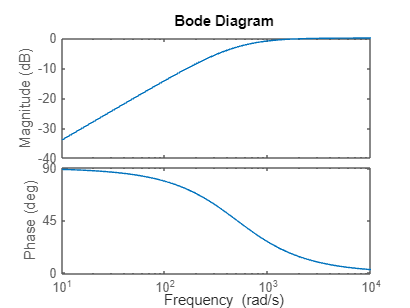

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000); % Frequency span til bodeplot
s = tf('s');                 % Complex Variable

numG = s*0.2;                             % numerator
denG = 100+s*0.2; % denominator

% Overførings Funktion 
G = numG/denG;
    bode(G)

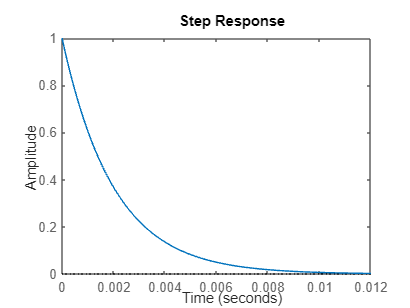

    step(G)

stepinfo(G)

ans = struct with fields:
         RiseTime: 0
    TransientTime: 0.0078
     SettlingTime: NaN
      SettlingMin: 6.6069e-04
      SettlingMax: 1
        Overshoot: Inf
       Undershoot: 0
             Peak: 1
         PeakTime: 0


## Q6

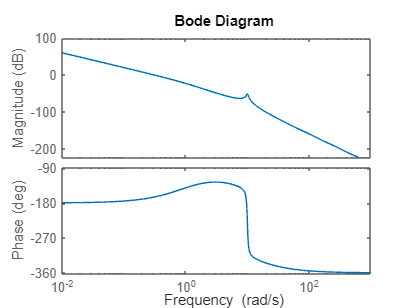


clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000); % Frequency span til bodeplot
s = tf('s');                 % Complex Variable
% 
% numG = (s-10)*(s+50);       NOT 1                      % numerator
% denG = (s*(s^2+100)); % denominator


% numG = (s-10);      NOT2                       % numerator
% denG = s^2+100; % denominator

% numG = (s-10);         not 3                     % numerator
% denG = s-1;

numG = (s-10);           %YES                 % numerator
denG = s*(s*(s^2+0.5*s+100))*(s-1);

% numG = (s-10)^2;        NOT5                   % numerator
% denG = s*(s^2+100);

% Overførings Funktion 
G = numG/denG;
    bode(G)

## Q7

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000); % Frequency span til bodeplot
s = tf('s');    

syms x F(t) c m k

eqn = m*s^2 + c*sqrt(s)+k == F(t)

Error using sym>tomupad
Unable to convert 'tf' to 'sym'.

Error in sym (line 273)
                S.s = tomupad(x);

Error in sym/privResolveArgs (line 1073)
                    argout{k} = sym(arg);

Error in 

## Q8

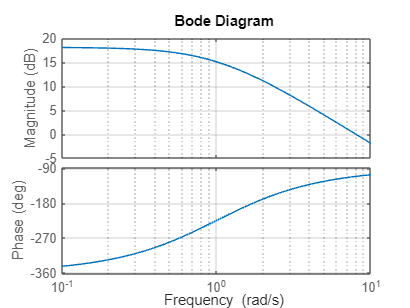

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000); % Frequency span til bodeplot
s = tf('s');  
numG = 8*(s+1);                             % numerator
denG = (s-1)^2; % denominator

% Overførings Funktion 
G = numG/denG;
bode(G),grid

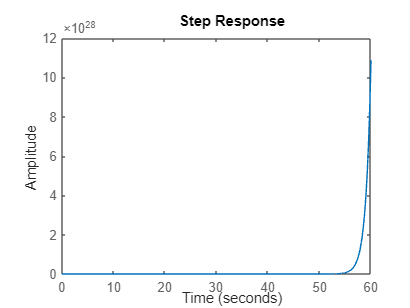

step(G);

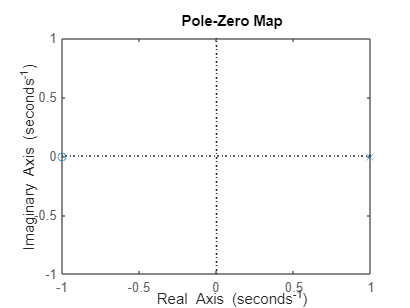

pzplot(G);

Gcl=(G/(1+G))

Gcl =
 
     8 s^3 - 8 s^2 - 8 s + 8
  ------------------------------
  s^4 + 4 s^3 - 2 s^2 - 12 s + 9
 
Continuous-time transfer function.
Model Properties


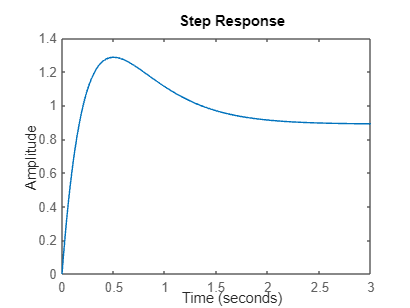

step(Gcl)

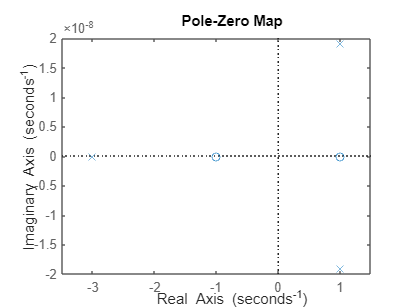


pzplot(Gcl)

## Q9 Vender vi tilbage til 

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000); % Frequency span til bodeplot
s = tf('s');  
K1=13.35; % set = 0.58
K2=0.1001;

% K1=10; % set = 0.9
% K2=0.15;
% 
% K1=11.4; % set= 0.9015
% K2=0.19;
% 
% K1=12.4;
% K2=0.25;

% K1=1;
% K2=1;
numG1 = 100;                             % numerator
denG1 = 1+0.2*s; % denominator
numG2 = 1;                             % numerator
denG2 = 20*s;


% Overførings Funktion 
G1 = numG1/denG1;
G2 = numG2/denG2;
Gk2= G1/(1+G1*K2);

Gfb=(K1*Gk2*G2);
Gcl=Gfb/(1+Gfb);

stepinfo(Gcl)

ans = struct with fields:
         RiseTime: 0.3224
    TransientTime: 0.5864
     SettlingTime: 0.5864
      SettlingMin: 0.9012
      SettlingMax: 0.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9999
         PeakTime: 1.2998


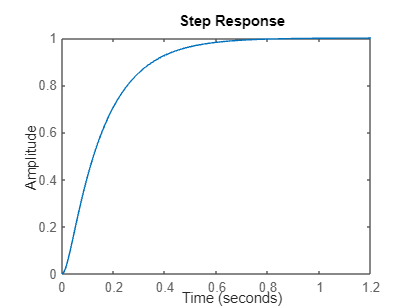

step(Gcl)

## Q10




clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000); % Frequency span til bodeplot
s = tf('s');  
numG = 10;                             % numerator
denG = (s+2)*(s+3); % denominator
Kp= 2

Kp = 2

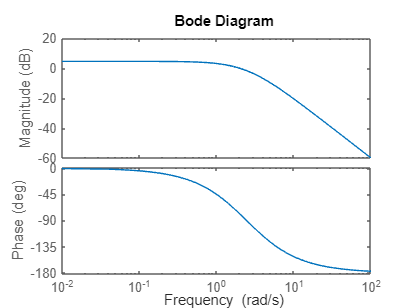

% Overførings Funktion 
G = numG/denG;
bode(G)


zero(G)


ans =

  0×1 empty double column vector



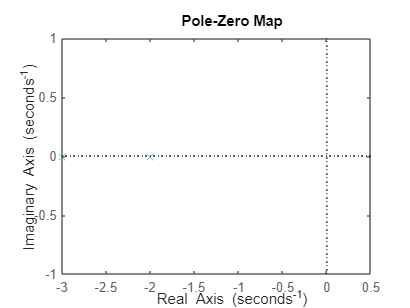

G0= 10/6;
pzplot(G)


% har sat 4 ind så den gange på det er ente 0.22(0.23) ellers fik jeg
% 0.9231
Ge = 1/(1+Kp*G)

Ge =
 
  s^2 + 5 s + 6
  --------------
  s^2 + 5 s + 26
 
Continuous-time transfer function.
Model Properties


ess = 0.9231

ess = freqresp(s*Ge*(4/s),0)


## Q11



KM = db2mag(-6.07)

KM = 0.4972

## Q14 se lecture 12 har et muligt svar

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000); % Frequency span til bodeplot
s = tf('s');

Magyd = db2mag(-22.1102)

Magyd = 0.0784

MagCl = db2mag(-0.172)

MagCl = 0.9804


Kp = -1/MagCl

Kp = -1.0200

Kpm = Magyd - Kp

Kpm = 1.0984

## Q15


clf;
clear all;
clc;

kp=1/-0.8889

kp = -1.1250

kp =




## Q16

ym = 180 + atand((-0.876)/(0.4825))

ym = 118.8459

## Q17

%
clf;
clear all;
clc;
b=db2mag(20)

b = 10

syms a 
s = tf('s'); 
eqn = b == 1/(sqrt(a))

$$eqn = 10=\frac{1}{\sqrt{a}}$$

sol1 = solve(eqn,a)

$$sol1 = \frac{1}{100}$$

var1 = double(sol1)

var1 = 0.0100

wc=25;
a = var1;
tau_d = 1/(sqrt(a)*wc);

Cd = (tau_d*s+1)/(tau_d*a*s+1);





## Q18

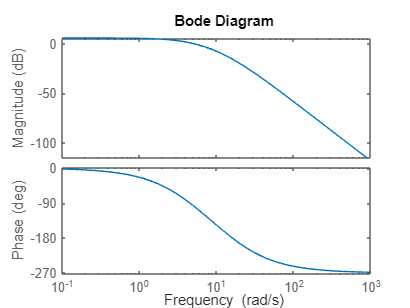

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000); % Frequency span til bodeplot
s = tf('s');  
numG = 1224;                             % numerator
denG = s^3+30*s^2+257*s+612; % denominator

% Overførings Funktion 
G = numG/denG;
bode(G)


[mag,phase] = bode(G,w); % Magnitude og Phase til Func
mag = squeeze(mag);
phase = squeeze(phase);

% vairabler
ym=75;    % Phase margin
Ni=3;     % Ni
a=0.05;      % Alpha til Lead   

%Ni = wc*tau_i  % anden måde at regne tau i ud på. 

% Phase bidrag
phCi = atand(-1/Ni);  % I-leads phase contribution
phCm = asind((1-a)/(1+a));  % D leds phase cont  
    Gphas=-180+ym-phCi-phCm % Total phase contribution + wanted phase margin. 

Gphas = -151.3563


% Finding the wanted phase margin
% NB NB !!! remember to look at bodeplot to see where we wont to find it 
% 
p_c =find(phase > Gphas,1,'last');
wc=w(p_c);  % calculated 

tau_i = Ni*(1/wc)

tau_i = 0.2838

tau_d = 1/(sqrt(a)*wc);
% I / D TF.
Ci = ((tau_i*s+1)/(tau_i*s));
Cd = (tau_d*s+1)/(tau_d*a*s+1);

Kp = 1/(abs(freqresp(Ci*Cd*G,wc)))

Kp = 0.5444

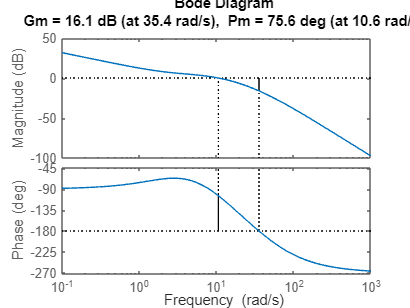


margin(Ci*Cd*G*Kp)

## Q19




% har svaret F=1/G



## Q20

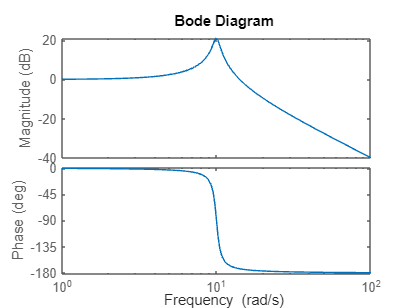



clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,1000); % Frequency span til bodeplot
s = tf('s');  
w_n=10;
z=0.0441;
numG = w_n^2;                             % numerator
denG = s^2+2*z*w_n*s+w_n^2; % denominator

% Overførings Funktion 
G = numG/denG;
bode(G)


maxdb = 21.0986

maxdb = 21.0986

MagGain = db2mag(-21.0986)

MagGain = 0.0881


ts = 1/MagGain

ts = 11.3483

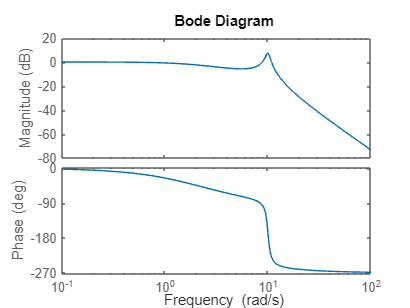

tf = 0.47;
gf= 1/(tf*s+1);

Gtf = gf*G;
bode(Gtf)

## q3

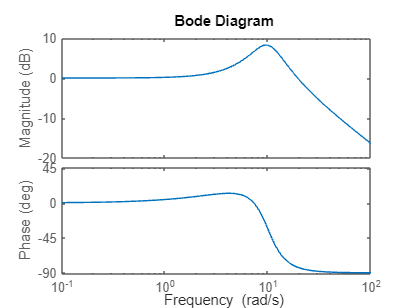

clf;
clear all;
clc;
%      Første model brugt
w = linspace(1e-4,120,50000); % Frequency span til bodeplot
s = tf('s');  

numG = 15*s+100;                             % numerator
denG = s^2+7*s+100; % denominator
G = numG/denG;
bode(G)

pole(G)

ans =   -3.5000 + 9.3675i
  -3.5000 - 9.3675i


zero(G)

ans = -6.6667